## Code For Running the Solver

*(May take more than 1-2 minutes depending on settings)*

% runs python file, collects relevant file names, then stores as MATLAB string
file_names_arr= pyrunfile("Finite_difference.py", 'L_files') 
file_names_arr = cell(file_names_arr)
file_names = string(file_names_arr{1})
fish_file_names = string(file_names_arr{2})

for i = 1:length(file_names)
    % Reads data for each time step and graphs it using graph function (at bottom of file)
    nodes = readtable(file_names(1, i))
    fish = readtable(fish_file_names(1, i))
    
    graph(nodes, fish)
end

## Code for displaying vortices that appear when the initial velocity of the flow is equal to zero.

Results may be replicated by setting **dt = 0.0005, duration = 0.002, v_i = 0**

v_file_names = ["Significant_Outputs/Vortices/nodes0.0.txt", "Significant_Outputs/Vortices/nodes0.0005.txt", "Significant_Outputs/Vortices/nodes0.001.txt", "Significant_Outputs/Vortices/nodes0.0015.txt"]
v_fish_file_names = ["Significant_Outputs/Vortices/fish0.0.txt", "Significant_Outputs/Vortices/fish0.0005.txt", "Significant_Outputs/Vortices/fish0.001.txt", "Significant_Outputs/Vortices/fish0.0015.txt"]

for i = 1:length(v_file_names)
    nodes = readtable(v_file_names(1, i))
    fish = readtable(v_fish_file_names(1, i))
    
    graph(nodes, fish)
end

## Code for displaying output when 26mm/s is used as the initial velocity.

Results may be replicated by setting **dt = 0.0001, duration = 0.0004, v_i = 26 **(these settings were prone to blowing up with a larger duration or dt)

ts_file_names = ["Significant_Outputs/Finite_Diff_26mms/nodes0.0.txt", "Significant_Outputs/Finite_Diff_26mms/nodes0.0001.txt", "Significant_Outputs/Finite_Diff_26mms/nodes0.0002.txt", "Significant_Outputs/Finite_Diff_26mms/nodes0.00030000000000000003.txt"]

ts_file_names = 1×4 string array
    "Significant_Outputs/Finite_Diff_26mms/nodes0.0.txt"    "Significant_Outputs/Finite_Diff_26mms/nodes0.0001.txt"    "Significant_Outputs/Finite_Diff_26mms/nodes0.0002.txt"    "Significant_Outputs/Finite_Diff_26mms/nodes0.00030000000000000003.txt"


ts_fish_file_names = ["Significant_Outputs/Finite_Diff_26mms/fish0.0.txt", "Significant_Outputs/Finite_Diff_26mms/fish0.0001.txt", "Significant_Outputs/Finite_Diff_26mms/fish0.0002.txt", "Significant_Outputs/Finite_Diff_26mms/fish0.00030000000000000003.txt"]

ts_fish_file_names = 1×4 string array
    "Significant_Outputs/Finite_Diff_26mms/fish0.0.txt"    "Significant_Outputs/Finite_Diff_26mms/fish0.0001.txt"    "Significant_Outputs/Finite_Diff_26mms/fish0.0002.txt"    "Significant_Outputs/Finite_Diff_26mms/fish0.00030000000000000003.txt"


nodes = 714×7 table
     Var1        Var2      Var3    Var4     Var5      Var6    Var7
    _______    ________    ____    ____    _______    ____    ____

    -27.857     -9.2857     0       23     -6.6258     0       0  
    -27.857     -8.5714     0       21     -9.2853     0       0  
    -27.857     -7.8571     0       20     -10.519     0       0  
    -27.857     -7.1429     0       18     -10.877     0       0  
    -27.857     -6.4286     0       17     -11.111     0       0  
    -27.857     -5.7143     0       17     -11.098     0       0  
    -27.857          -5     0       16     -11.116     0       0  
    -27.857     -4.2857     0       16     -11.035     0       0  
    -27.857     -3.5714     0       15     -10.996     0       0  
    

fish = 70×7 table
     Var1        Var2      Var3    Var4    Var5    Var6    Var7
    _______    ________    ____    ____    ____    ____    ____

        -15    -0.71429     1       26      0       0       0  
        -15           0     1       26      0       0       0  
        -15           0     1       26      0       0       0  
        -15     0.71429     1       26      0       0       0  
    -12.857     -1.4286     1       26      0       0       0  
    -12.857    -0.71429     1       26      0       0       0  
    -12.857           0     1       26      0       0       0  
    -12.857           0     1       26      0       0       0  
    -12.857     0.71429     1       26      0       0       0  
    -12.857      1.4286     1       26 

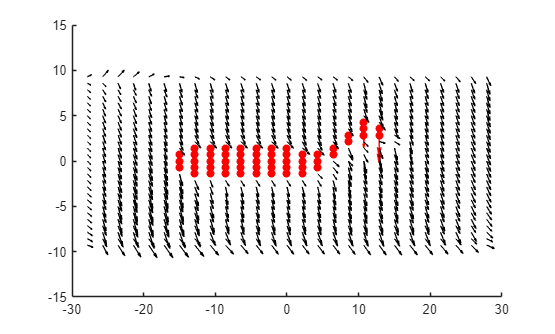

nodes = 714×7 table
     Var1        Var2      Var3    Var4     Var5     Var6    Var7
    _______    ________    ____    ____    ______    ____    ____

    -27.857     -9.2857     0       26     18.063     0       0  
    -27.857     -8.5714     0       32       21.2     0       0  
    -27.857     -7.8571     0       37     33.801     0       0  
    -27.857     -7.1429     0       41      34.74     0       0  
    -27.857     -6.4286     0       44     40.759     0       0  
    -27.857     -5.7143     0       48     39.536     0       0  
    -27.857          -5     0       50     41.048     0       0  
    -27.857     -4.2857     0       52     38.206     0       0  
    -27.857     -3.5714     0       52     36.726     0       0  
    -27.857    

fish = 70×7 table
     Var1        Var2      Var3    Var4      Var5      Var6    Var7
    _______    ________    ____    ____    ________    ____    ____

        -15    -0.71429     1      -30      -12.912     0       0  
        -15           0     1      -25     -0.43548     0       0  
        -15           0     1      -23      0.77616     0       0  
        -15     0.71429     1      -22       5.2868     0       0  
    -12.857     -1.4286     1      -26       16.321     0       0  
    -12.857    -0.71429     1      -16       23.299     0       0  
    -12.857           0     1      -13       26.398     0       0  
    -12.857           0     1      -13       21.213     0       0  
    -12.857     0.71429     1      -14       8.8296     0      

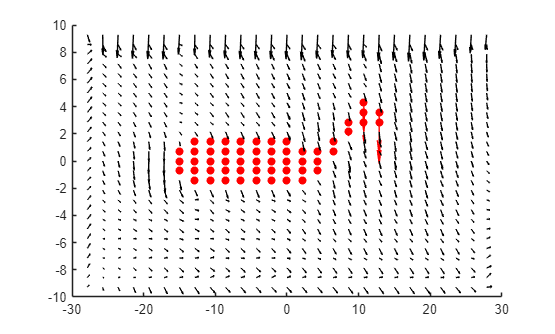

nodes = 714×7 table
     Var1        Var2      Var3    Var4      Var5       Var6    Var7
    _______    ________    ____    ____    _________    ____    ____

    -27.857     -9.2857     0        0        -46.63     0       0  
    -27.857     -8.5714     0       -5       -62.101     0       0  
    -27.857     -7.8571     0      -14        -77.73     0       0  
    -27.857     -7.1429     0      -19       -79.923     0       0  
    -27.857     -6.4286     0      -25        -85.12     0       0  
    -27.857     -5.7143     0      -27       -81.813     0       0  
    -27.857          -5     0      -31       -80.688     0       0  
    -27.857     -4.2857     0      -32       -72.695     0       0  
    -27.857     -3.5714     0      -34       -65.76

fish = 70×7 table
     Var1        Var2      Var3    Var4     Var5      Var6    Var7
    _______    ________    ____    ____    _______    ____    ____

        -15    -0.71429     1       24     -74.975     0       0  
        -15           0     1        4     -121.62     0       0  
        -15           0     1       -7     -89.672     0       0  
        -15     0.71429     1       -4     -108.05     0       0  
    -12.857     -1.4286     1       -3     -140.79     0       0  
    -12.857    -0.71429     1      -18     -152.29     0       0  
    -12.857           0     1      -18     -151.02     0       0  
    -12.857           0     1      -17     -143.19     0       0  
    -12.857     0.71429     1       -9     -110.11     0       0  
    -1

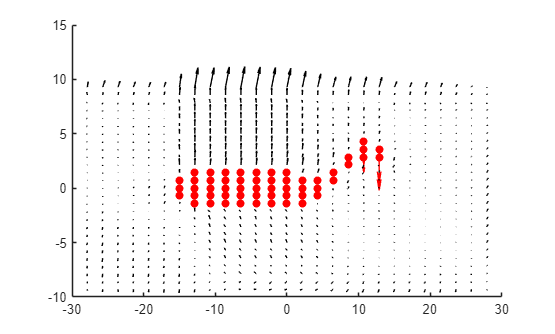

nodes = 714×7 table
     Var1        Var2      Var3    Var4     Var5     Var6    Var7
    _______    ________    ____    ____    ______    ____    ____

    -27.857     -9.2857     0       42     95.276     0       0  
    -27.857     -8.5714     0       85      151.5     0       0  
    -27.857     -7.8571     0      108     192.01     0       0  
    -27.857     -7.1429     0      133     213.32     0       0  
    -27.857     -6.4286     0      146     219.78     0       0  
    -27.857     -5.7143     0      163     224.91     0       0  
    -27.857          -5     0      169      215.1     0       0  
    -27.857     -4.2857     0      179      209.5     0       0  
    -27.857     -3.5714     0      179     188.54     0       0  
    -27.857    

fish = 70×7 table
     Var1        Var2      Var3    Var4     Var5     Var6    Var7
    _______    ________    ____    ____    ______    ____    ____

        -15    -0.71429     1       -10    259.23     0       0  
        -15           0     1        20    283.16     0       0  
        -15           0     1        37     306.5     0       0  
        -15     0.71429     1        24    358.35     0       0  
    -12.857     -1.4286     1       -67    298.73     0       0  
    -12.857    -0.71429     1       -71    138.58     0       0  
    -12.857           0     1       -25    320.79     0       0  
    -12.857           0     1       -11    255.84     0       0  
    -12.857     0.71429     1        66    440.85     0       0  
    -12.857      

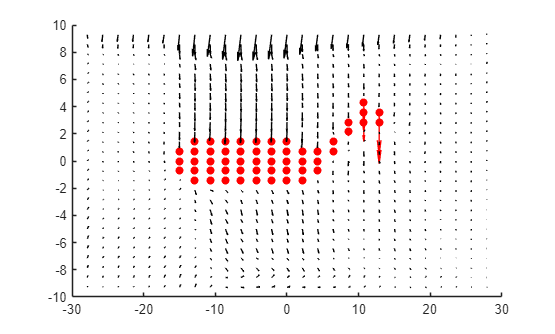


for i = 1:length(ts_file_names)
    nodes = readtable(ts_file_names(1, i))
    fish = readtable(ts_fish_file_names(1, i))
    
    graph(nodes, fish)
end

function graph(nodes, fish)
    figure()
    hold on
    % Graphing scatter plot of nodes that are within the fish
    scatter(fish{:, 1}, fish{:, 2}, 'filled', 'red')
    % Graphing body velocity of the fish
    quiver(fish{:, 1}, fish{:, 2}, fish{:, 6}, fish{:, 7}, 'filled', 'red')

    % Graphing vector field of water around the fish 
    quiver(nodes{:, 1}, nodes{:, 2}, nodes{:, 4}, nodes{:, 5}, 'filled', 'black')
    drawnow;
    exportgraphics(gca, "nodes.gif", 'Append', true);
    hold off
end